clc;    % Clear the command window.
close all;  % Close all figures (except those of imtool.)
clearvars;
workspace;  % Make sure the workspace panel is showing.
format long g;
format compact;
fontSize = 16;
fprintf('Beginning to run %s.m ...\n', mfilename);

Beginning to run LiveEditorEvaluationHelperE354177028.m ...


%-----------------------------------------------------------------------------------------------------------------------------------
% Read in image.
[baseFileName, pathname] = uigetfile({'*.jpg';'*.png'},'File Selector');
fullFileName = strcat(pathname, baseFileName);
I = imread(fullFileName);
% Check if file exists.
if ~exist(fullFileName, 'file')
	% The file doesn't exist -- didn't find it there in that folder.
	% Check the entire search path (other folders) for the file by stripping off the folder.
	fullFileNameOnSearchPath = baseFileName; % No path this time.
	if ~exist(fullFileNameOnSearchPath, 'file')
		% Still didn't find it.  Alert user.
		errorMessage = sprintf('Error: %s does not exist in the search path folders.', fullFileName);
		uiwait(warndlg(errorMessage));
		return;
	end
end
% It's not an RGB image!  It's an indexed image, so read in the indexed image...
rgbImage = imread(fullFileName);
[rows, columns, numberOfColorChannels] = size(rgbImage)

rows =    256

columns =    256

numberOfColorChannels =      3

% Display the test image.
subplot(2, 2, 1);
imshow(rgbImage, []);
axis('on', 'image');
caption = sprintf('Image : "%s"', baseFileName);
title(caption, 'FontSize', fontSize, 'Interpreter', 'None');
drawnow;
hp = impixelinfo(); % Set up status line to see values when you mouse over the image.
% Set up figure properties:
% Enlarge figure to full screen.
hFig1 = gcf;
hFig1.Units = 'Normalized';
hFig1.WindowState = 'maximized';
% Get rid of tool bar and pulldown menus that are along top of figure.
% set(gcf, 'Toolbar', 'none', 'Menu', 'none');
% Give a name to the title bar.
hFig1.Name = 'Demo by Image Analyst';
[mask, maskedRGBImage] = createMask(rgbImage);
% Take just the largest regions:
mask = bwareafilt(mask, 1);
% Fill Holed.
mask = imfill(mask, 'holes');
% Display the initial mask image.
subplot(2, 2, 2);
imshow(mask, []);
hp = impixelinfo(); % Set up status line to see values when you mouse over the image.
axis('on', 'image');
title('Mask', 'FontSize', fontSize, 'Interpreter', 'None');
drawnow;
% Mask the image using bsxfun() function to multiply the mask by each channel individually.  Works for gray scale as well as RGB Color images.
maskedRgbImage = bsxfun(@times, rgbImage, cast(mask, 'like', rgbImage));
% Display the final masked image.
subplot(2, 2, 3);
imshow(maskedRgbImage, []);
axis('on', 'image');
title('Masked Image', 'FontSize', fontSize, 'Interpreter', 'None');
drawnow;
hp = impixelinfo(); % Set up status line to see values when you mouse over the image.
% Display the final masked image of the background by inverting the mask.
% Mask the image using bsxfun() function to multiply the mask by each channel individually.  Works for gray scale as well as RGB Color images.
backgroundImage = bsxfun(@times, rgbImage, cast(~mask, 'like', rgbImage));
subplot(2, 2, 4);
imshow(backgroundImage, []);
axis('on', 'image');
title('Background Image', 'FontSize', fontSize, 'Interpreter', 'None');
drawnow;
hp = impixelinfo(); % Set up status line to see values when you mouse over the image.
%-------------------------------------------------------------------------------------------------------------
% Make measurements
props = regionprops(mask, 'Area', 'Centroid')

props = struct with fields:
        Area: 28733
    Centroid: [142.597709950231 142.080604183343]

allAreas = [props.Area];
xyCentroids = vertcat(props.Centroid);
subplot(2, 2, 2);
hold on;
for k = 1 : length(props)
	x = xyCentroids(k, 1);
	y = xyCentroids(k, 2);
	txt = sprintf('  (x, y) = (%.1f, %.1f).  Area = %d', ...
		x, y, allAreas(k));
	text(x, y, txt, 'Color', 'r', 'FontWeight', 'bold');
	plot(x, y, 'r+', 'MarkerSize', 25, 'LineWidth', 2);
end
% Get boundary.
boundaries = bwboundaries(mask);
boundaries = boundaries{1}; % Extract from cell.
x = boundaries(:, 2);
y = boundaries(:, 1);
plot(x, y, 'r-', 'LineWidth', 3);
fprintf('Done running %s.m ...\n', mfilename);

Done running LiveEditorEvaluationHelperE354177028.m ...


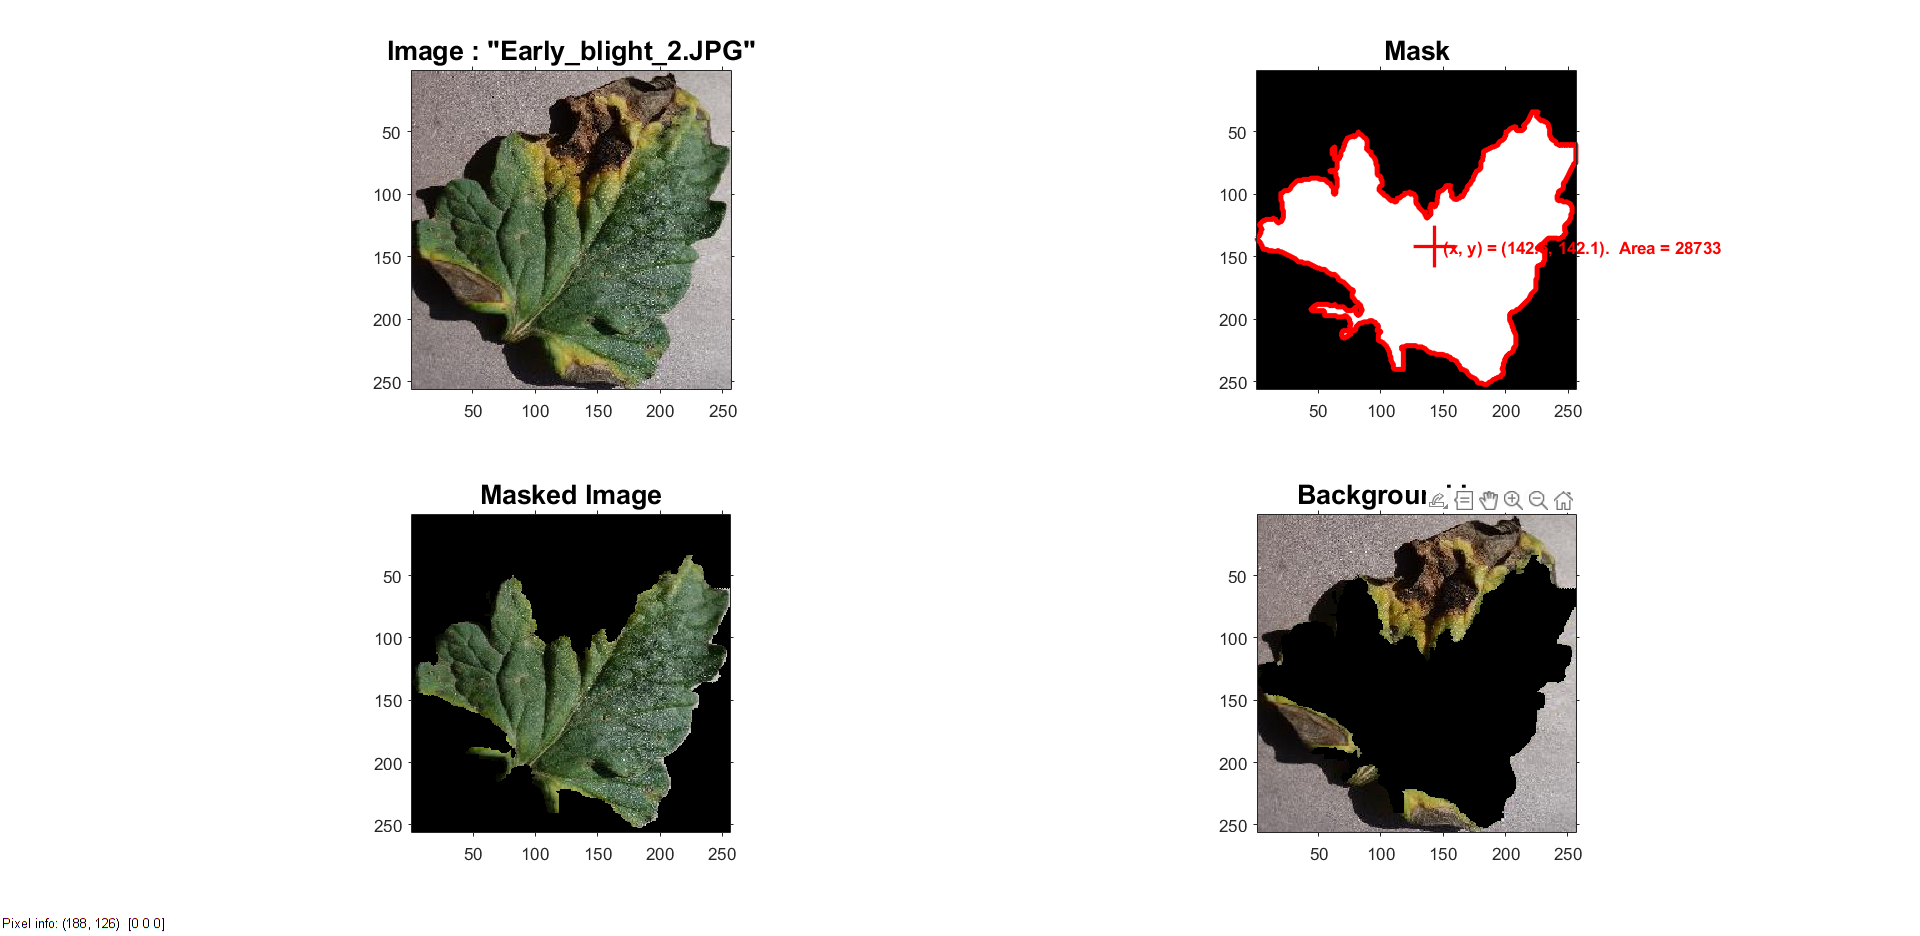

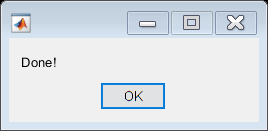

msgbox('Done!');

function [BW,maskedRGBImage] = createMask(RGB)
%createMask  Threshold RGB image using auto-generated code from colorThresholder app.
%  [BW,MASKEDRGBIMAGE] = createMask(RGB) thresholds image RGB using
%  auto-generated code from the colorThresholder app. The colorspace and
%  range for each channel of the colorspace were set within the app. The
%  segmentation mask is returned in BW, and a composite of the mask and
%  original RGB images is returned in maskedRGBImage.
% Auto-generated by colorThresholder app on 01-Nov-2020
%------------------------------------------------------
% Convert RGB image to chosen color space
I = rgb2hsv(RGB);
% Define thresholds for channel 1 based on histogram settings
channel1Min = 0.183;
channel1Max = 0.400;
% Define thresholds for channel 2 based on histogram settings
channel2Min = 0.000;
channel2Max = 1.000;
% Define thresholds for channel 3 based on histogram settings
channel3Min = 0.000;
channel3Max = 1.000;
% Create mask based on chosen histogram thresholds
sliderBW = (I(:,:,1) >= channel1Min ) & (I(:,:,1) <= channel1Max) & ...
	(I(:,:,2) >= channel2Min ) & (I(:,:,2) <= channel2Max) & ...
	(I(:,:,3) >= channel3Min ) & (I(:,:,3) <= channel3Max);
BW = sliderBW;
% Initialize output masked image based on input image.
maskedRGBImage = RGB;
% Set background pixels where BW is false to zero.
maskedRGBImage(repmat(~BW,[1 1 3])) = 0;
end